% データリスト読み込み
list = dir('/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0605/*.csv');
% dataの階層
pl = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0605/';

% データ
data1 = readmatrix('/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0605/04.csv');

## 変数

視点・終点 :  gageファイルの3列目に始点と終点の列数を記入

% 巻き数
m = 9;

% 始点
gage1 = 1301;

% 終点
gage2 = 2529;

% 巻きの高さ
H = 70;

## データ整理

基本変更しない

% データ数
n = gage2 - gage1 + 1;
% データ
Z = data1(6:end, gage1:gage2) .* (-1);
Z=filloutliers(Z,"center");
Z = fillmissing(Z,'previous');

Z =     8.1900    9.1500    9.7900    9.7000    9.6900   10.1500    9.8500   10.1800   10.7600   11.1200   12.1000   13.1600   29.6000   30.7700   32.3900   33.3600   35.4800   36.5900   37.3900   37.9300   38.9350   40.4700   42.2350   43.2200   44.0850   45.5400   47.0950   48.5800   50.0700   51.7800   54.8800   58.0450   60.5200   63.1200   65.2900   67.4300   68.7200   70.6650   73.4350   75.0000   76.2650   78.0800   80.1400   82.4300   84.5400   87.2500   90.7300   93.2900   95.9050   97.6300
    7.4200    8.6900    9.0800    9.4200    9.9000   10.7600   11.1400   11.2300   11.5400   11.9600   12.7800   13.2900   13.9800   30.7700   32.3900   33.3600   35.4800   36.5900   37.3900   37.9300   38.9350   40.4700   42.2350   43.2200   44.0850   45.5400   47.0950   48.5800   50.0700   51.7800   54.8800   58.0450   60.5200   63.1200   65.2900   67.4300   68.7200   70.6650   73.4350   75.0000   76.2650   78.0800   80.1400   82.4300   84.5400   87.2500   90.7300   93.2900   95.9050   97

% データサイズ
sz = size(Z);
row = sz(1);
% プロット位置
theta = linspace(0, 2 * m * pi, n);
x = 50 * cos(theta);
y = 50 * sin(theta);
h = linspace(H, 0, n);
t = linspace(0, (row - 0.01) / 100, row);
% colorbar用
zmax = max(max(Z))

zmax = 848.7400

zmin = min(min(Z))

zmin = 7.4000

zmean = mean(Z);
zstd=rms(Z);
zmin=zmean-2 * zstd;
zmax=zmean+2 * zstd;

a=linspace(1,1628,15);
a=round(a);

X = 50 * cos(theta);
Y = 50 * sin(theta);
H = linspace(H, 0, n);

## 動画セクション

基本変更しない

T = 0.01:0.01:row / 100;
for i = 1:length(T)
    % z{i} = Z(i,:)-Z(1,:);
    % z{i} = Z(i,:);
    if i==1
        z(i,:) = Z(i,:)-Z(i,:);
        M=max(z(1,:));
        m=min(z(1,:));
    end
    if i>=2
        z(i,:) = Z(i,:)-Z(i-1,:);
        if max(z(i,:))>M
            M=max(z(i,:));
        end
        if min(z(i,:))<m
            m=min(z(i,:));
        end
    end
end

% M=845
% m=10
M

M = 357.5700

m

m = -358.7200

% for i = 1 to 3010
%     plot(z)
% end
z=filloutliers(z,"center");
M=max(max(z))

M = 8.1600

m=min(min(z))

m = -8

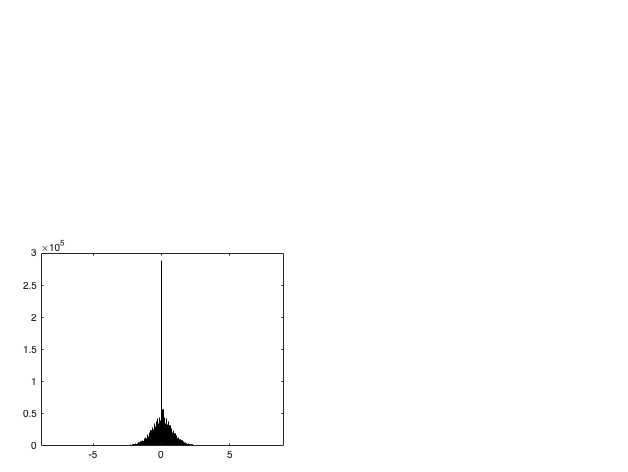

histogram(z)

max(max(z))

ans = 8.1600

fig = figure; % Figure オブジェクトの生成
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
zlim([0 75]);
frames(row) = struct('cdata', [], 'colormap', jet); % 各フレームの画像データを格納する配列
H=scatter3(x, y, h, [], z(i,:), 'filled');
view(45, 45)
daspect([1 1 1])
for i = 1:row
    set(H, 'CData', z(i,:));
    clim([m M]);
    axis off
    drawnow;
    frames(i) = getframe(fig);
end

video = VideoWriter(append(pl,'0609_差分.mp4'), 'MPEG-4');
video.FrameRate = 100;
open(video); 
writeVideo(video, frames);
close(video);